
sep =5;
s = 10;
M = sqrt(sep^2 / 4 / s)
p_vec_micro = [round(linspace(10, 3000, 50)), round(linspace(10, 2000, round(50*2/3)))+3000];
n_rep = 100;

clustering_acc = repelem(0, length(p_vec_micro));
clustering_acc_mat_p_micro = repmat(clustering_acc, n_rep,1);


for i = 1:length(p_vec_micro)
    p = p_vec_micro(i)
    sparse_mean = [repelem(1,s), repelem(0,p-s)];
    mu_1 =  -M * sparse_mean;
    mu_2 =   M * sparse_mean;
    norm(mu_1 - mu_2)
    mu_1_mat = repmat(mu_1, n/2,1);
    mu_2_mat = repmat(mu_2, n/2,1);
    
    for j = 1:n_rep
        
    %data generation
        x = [ mu_1_mat ; mu_2_mat ] + sigma^2 * randn(n, p);
        A = (x * x')/ n; % original affinity matrix (or similarity matrix)
                    %scaling
    
        % solve SDP problem (implemented in kmeans_sdp.m)
        Z_org = kmeans_sdp(A, K);
        rounded_cluster_one = Z_org>rounding;
        cluster_one_est = find(rounded_cluster_one(:,1));
        rounded_cluster_two = Z_org<rounding;
        cluster_two_est = find(rounded_cluster_two(:,1));
    
        cluster_est = 1:n;
        cluster_est(cluster_one_est) = 1;
        cluster_est(cluster_two_est) = -1;

        cluster_acc = max( ...
            mean(cluster_true == cluster_est), ...
            mean(cluster_true == -cluster_est) ...
            );
        clustering_acc_mat_p_micro(j, i) = cluster_acc;
    end  
end

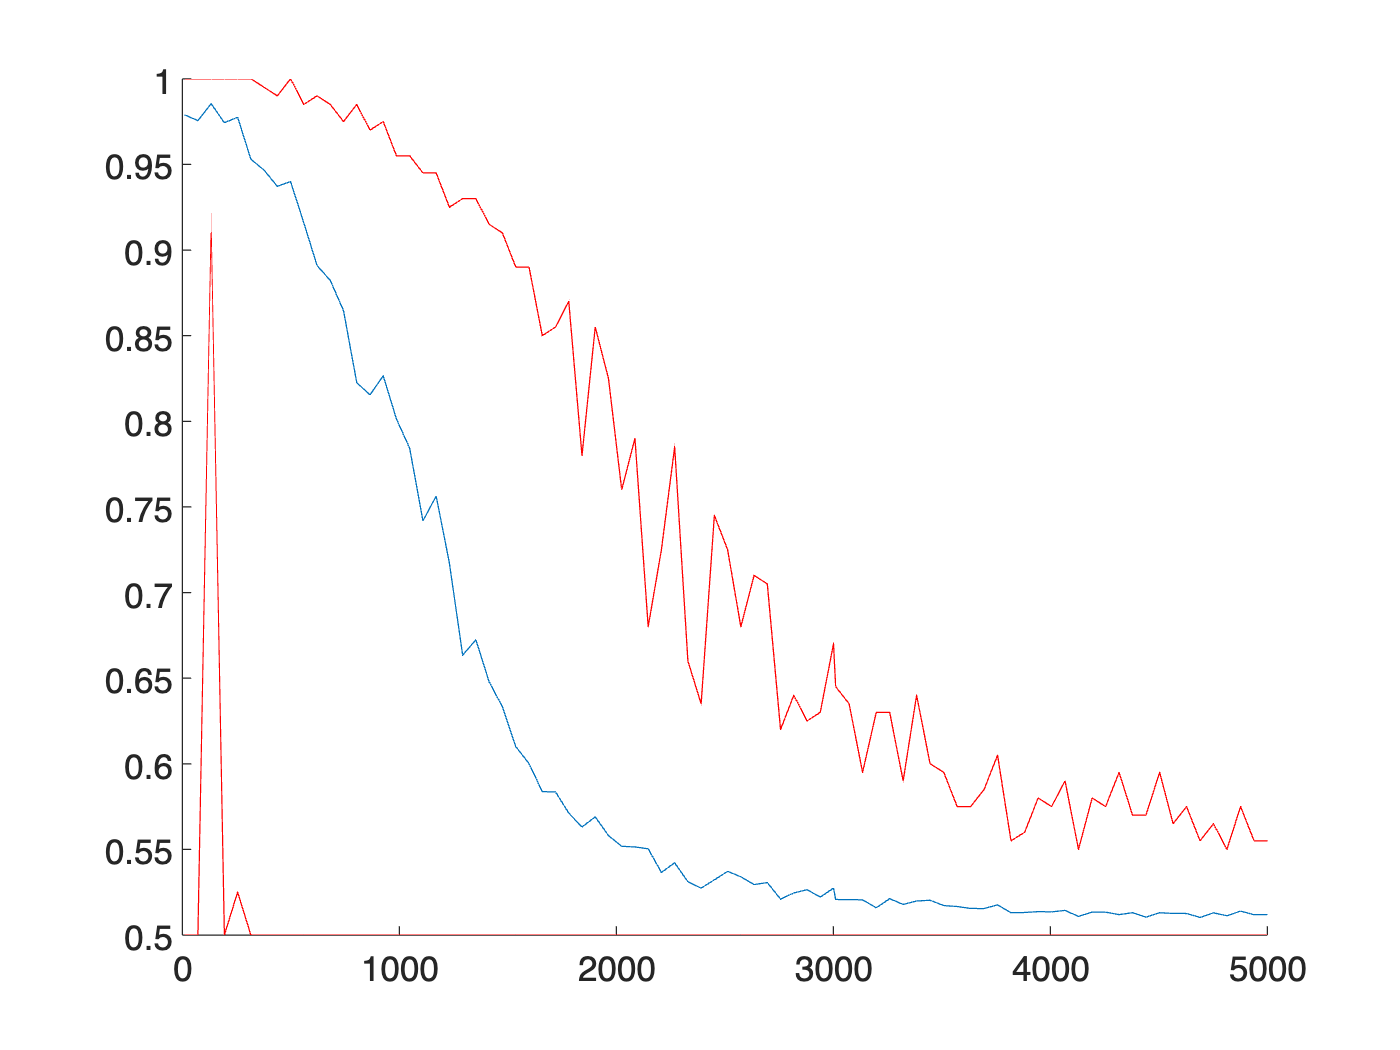

x = p_vec_micro;                     
y = mean(clustering_acc_mat_p_micro,1);
y_max = max(clustering_acc_mat_p_micro);
y_min = min(clustering_acc_mat_p_micro);


figure;
         

hold on
plot(x,y)
plot(x,y_max,'red')
plot(x,y_min,'red')
hold off